data = load('postprocessing.mat').data

data = 2018×20 table
                   file_name                   initial_velocity_cgs     weber        bond      ohnesorge                          parent_folder                          number_of_harmonics    max_width    contact_time_ms    coef_restitution    north_pole_min_height    north_pole_exp_min_height    max_contact_radius    spread_time_ms    spread_time_width_ms    contact_time_exp_ms    coef_rest_exp    max_contact_radius_exp    spread_time_exp_ms                                                                                                                                                                                                                  

sortrows(data(data.number_of_harmonics == 250, :), "weber")

ans = 219×20 table
                    file_name                     initial_velocity_cgs      weber        bond     ohnesorge                          parent_folder                          number_of_harmonics    max_width    contact_time_ms    coef_restitution    north_pole_min_height    north_pole_exp_min_height    max_contact_radius    spread_time_ms    spread_time_width_ms    contact_time_exp_ms    coef_rest_exp    max_contact_radius_exp    spread_time_exp_ms    energy_modes
    __________________________________________    ____________________    __________    ______    _

Hola

function plotter(data, column, varargin)
    xVals = data.weber;
    yVals = data.(column);
    
    hold on; xscale log; xlim([1e-4, 1]);
    if nargin >= 3
        plot(varargin{1}, xVals, yVals, 'DisplayName',sprintf('Nb harmonics = %d', data.number_of_harmonics(1)), ...
            'LineWidth',data.number_of_harmonics(1)/90);
    else
        plot(xVals, yVals, 'DisplayName',sprintf('Nb harmonics = %d', data.number_of_harmonics(1)));
    end
    hold off;
end

val = 0.01518835246835;
target_ohnesorge =   val * [0, 2];
target_harmonics = [90, 250];
close all;
for oh = target_ohnesorge
    h = subplot(1, length(target_ohnesorge), find(target_ohnesorge==oh));
    
    title(sprintf('Oh = %.3e', oh));
    for nb = target_harmonics
        data_filtered = sortrows(data(data.number_of_harmonics == nb & ...
            abs(data.ohnesorge - oh)./(data.ohnesorge+1e-16) < 0.03  & ...
            abs(data.bond - 0.0189)./data.bond < 0.05 & ...
            contains(data.parent_folder, 'v3'), :), 'weber');
        fprintf("Oh = %.3e, Nb = %d, experiments = %d\n", oh, nb, height(data_filtered))
        plotter(data_filtered, 'contact_time_ms', h);
    end
    legend('FontSize', 8);

end

Oh = 0.000e+00, Nb = 90, experiments = 48
Oh = 0.000e+00, Nb = 250, experiments = 83
Oh = 3.038e-02, Nb = 90, experiments = 72
Oh = 3.038e-02, Nb = 250, experiments = 95


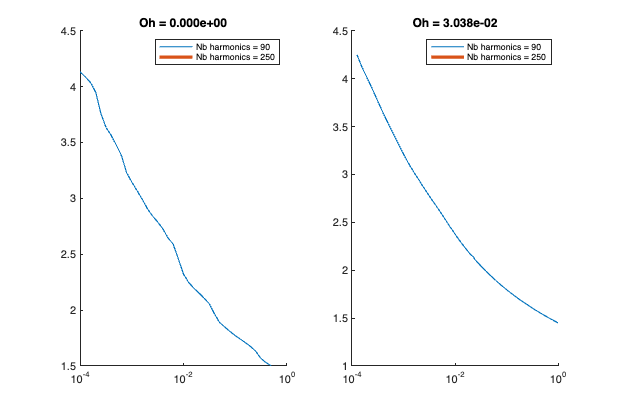

set(gcf, 'Position', [10, 10, 900, 600])